# Deep Learning

addpath("RandomImages/");

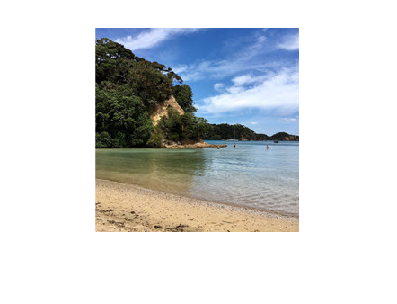

img1 = imread("file01.jpg");
imshow(img1);

## Using Neural Networks

Load a neural network:

net = imagePretrainedNetwork %load the neural network

net =   dlnetwork with properties:

         Layers: [68×1 nnet.cnn.layer.Layer]
    Connections: [75×2 table]
     Learnables: [52×3 table]
          State: [0×3 table]
     InputNames: {'data'}
    OutputNames: {'prob_flatten'}
    Initialized: 1

  View summary with summary.


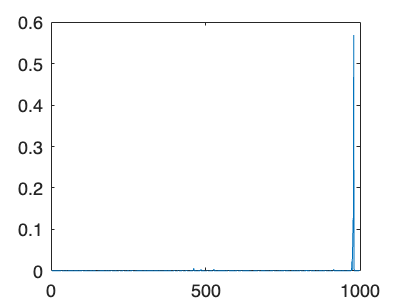

s1 = minibatchpredict(net,img1); % give the network an image
plot(s1); % plot the result, in this case we get a value 

[net,classes] = imagePretrainedNetwork; % load the network with its classes (categories)
c1 = scores2label(s1,classes) % transform the score of the picture given to the most probable category to get the reslt.

c1 = categorical
     seashore 


In this case the result is "seashore".

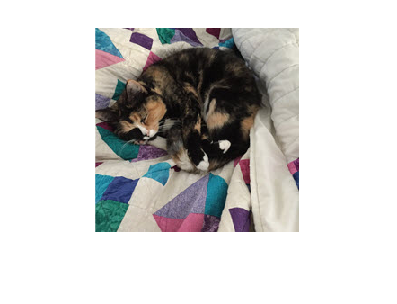

img2 = imread("file02.jpg");
imshow(img2);

s2 = minibatchpredict(net,img2);
c2 = scores2label(s2,classes)

c2 = categorical
     Gordon setter 


The result here is "Gordon Setter".

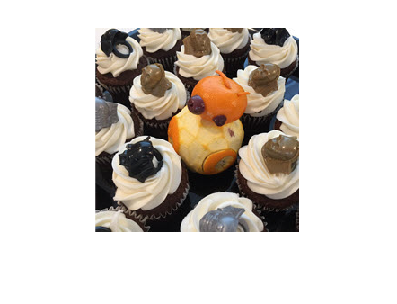

img3 = imread("file03.jpg");
imshow(img3);

s3 = minibatchpredict(net,img3);
c3 = scores2label(s3,classes)

c3 = categorical
     bakery 


The result is "bakery".

## Using Googlenet

[net,classes] = imagePretrainedNetwork("googlenet"); % load the network with its classes (categories)
s1 = minibatchpredict(net,img1); % give the network an image
c1 = scores2label(s1,classes) % transform the score of the picture given to the most probable category to get the reslt.

c1 = categorical
     seashore 


In this case the result is "seashore".

s2 = minibatchpredict(net,img2);
c2 = scores2label(s2,classes)

c2 = categorical
     Bernese mountain dog 


The result here is "Gordon Setter".

s3 = minibatchpredict(net,img3);
c3 = scores2label(s3,classes)

c3 = categorical
     bakery 


## Analyzing all images

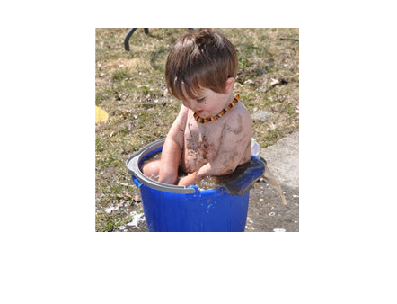

%ls("RandomImages/*.jpg")
imds = imageDatastore("RandomImages/*.jpg");
fname = imds.Files;
img = readimage(imds,7);
imshow(img);

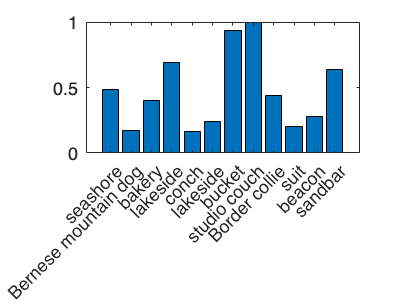

scores = minibatchpredict(net, imds);
preds = scores2label(scores,classes);
max(scores,[],2);
bar(max(scores,[],2));
xticklabels(preds);

## Adjust Input Images

The initial size of image 01 is:

img = imread("file01.jpg");
imshow(img)

sz = size(img)

sz =    227   227     3


Let us see the network characteristics:

summary(net);


   Initialized: true

   Number of learnables: 6.9M

   Inputs:
      1   'data'   224×224×3 images



Since the sizes do not match, we can rezise the image and see if the result chane:

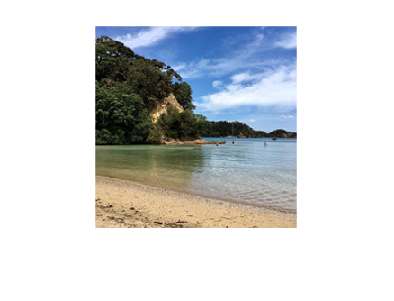

img = imresize(img,[224 224]);
imshow(img)

s = minibatchpredict(net,img);
c = scores2label(s,classes)

c = categorical
     seashore 


## Adjust for all Images

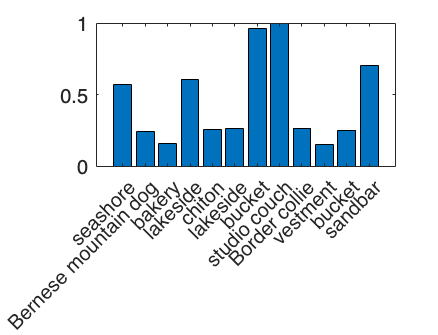

auds = augmentedImageDatastore([224 224], imds);
scores = minibatchpredict(net, auds);
preds = scores2label(scores,classes);
max(scores,[],2);
bar(max(scores,[],2));
xticklabels(preds);

We got some different results in this case.